**Graph-Based Method Notebook**

**Kuan-Min Lee**

**Graph-Based Segmentation Method:**

**Basic Theory explanation:**

Image as graphs have node (vertex) for **every pixel. Edges happen between pairs of pixels (p,q), **and there's an **affinity weight** for each edge **(measure similarity)**.

**Different types of edges:**

- **Fully connected edges:**

**            Pros: **capture all pairwise similarities

            **Cons: infeasible for most image (too much computation)**

          2**.  Neighboring pixels edges:**

**            Pros: very fast to compute**

**            Cons: only capture very local interaction**

**          3. Local neighborhood edges:**

**             Reasonably fast graph still very sparse**

**Relative Function:**

**lazysnapping(Image,Label-matrix,foremask,backmask);**

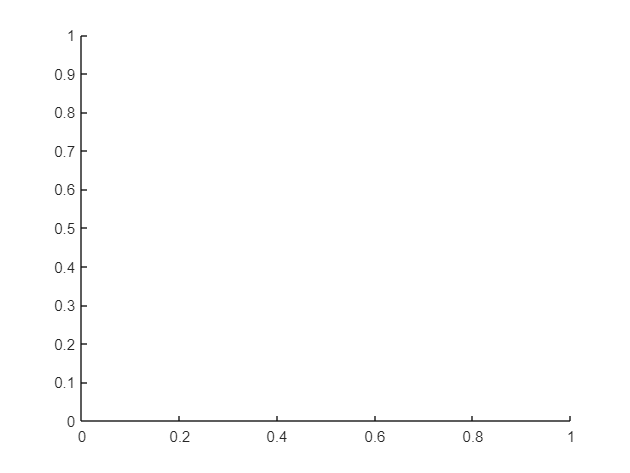

clear all
car_img=imread("car.jpg"); 
L=superpixels(car_img,500); % create label matrix (need more study on this function)
f = drawrectangle(gca,'Position',[135 180 270 180],'Color','g');
foreground = createMask(f,car_img);
b1 = drawrectangle(gca,'Position',[130 30 40 30],'Color','r');
b2 = drawrectangle(gca,'Position',[350 6 363 10],'Color','r');

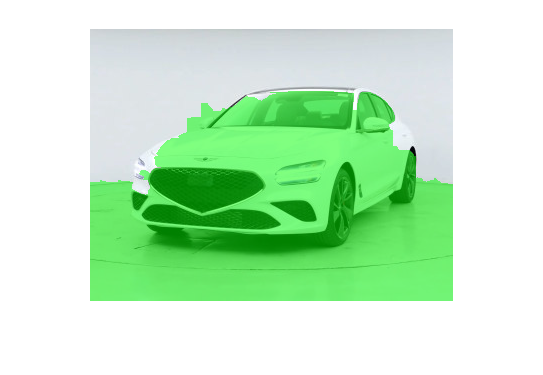

background = createMask(b1,car_img) + createMask(b2,car_img);
BW = lazysnapping(car_img,L,foreground,background);
imshow(labeloverlay(car_img,BW,'Colormap',[0 1 0]))

**Pros and Cons: **

**Pros:**

- It can be very adaptive to the need of the user (foreground and background setting)

- The region selected can be very adaptive in term of the information (texture, intensity, etc.) since it measures the affinity

**Cons:**

- It can be hard to define the foreground versus background

- Like threshold method, it allow only binary categorization (foreground and background)